Load Data

load("mnist.mat");

Iterate through the digits

for d=0:9
    

Read the images of the digit and reshape into 1D

   digits = digits_train(:, :, labels_train==d); % choose all images with digit d
   digits = reshape(im2double(digits), [784 size(digits, 3)]);
   % reshape this data into a 784xN matrix, where N is the number of images
   % with digit d
   % Every column is a sample digit d (that is our samples are stacked
   % column wise in the matrix)
 

Mean and translation of data points

  
   mean_vector = sum(digits, 2)/size(digits, 2);
   % mean is found by summing the column vectors
   digits = digits - mean_vector;
   % mean subtraction (needed for covariance)
   

Compression of Images along 84 dimensions

 [reduced_data, basis] = rerepresent_digits(digits, 84);
   % the function rerepresent_digits(digits, d) defined in
   % rerepresent_digits.m reduces the digits dataset into d dimensions
   % and returns it in reduced_data
   % we also want to know the directions (basis vectors) along which we reduced
   % the data and this is given in the basis matrix stacked column wise
   % Details of this is in the function
   

Reconstruct the image from the weights calculated earlier

   reconstructed = basis*reduced_data;
   % To reconstruct we multiply by bases (explained in the report)
   % Essentially this would ensure that the jth column in reconstructed is
   % the linear combination of the bases with coefficietnts =  inner products 
   % with the jth sample.
   
   

plot the images

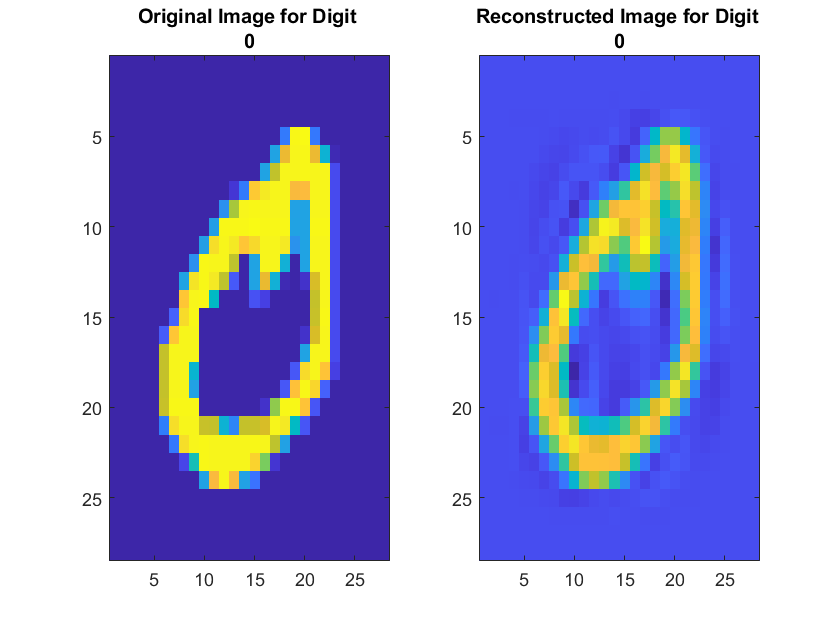

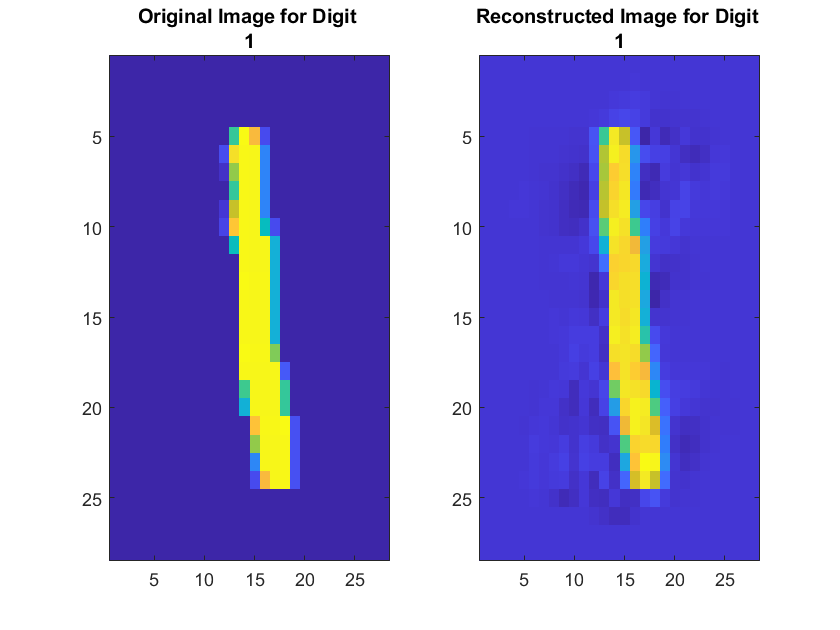

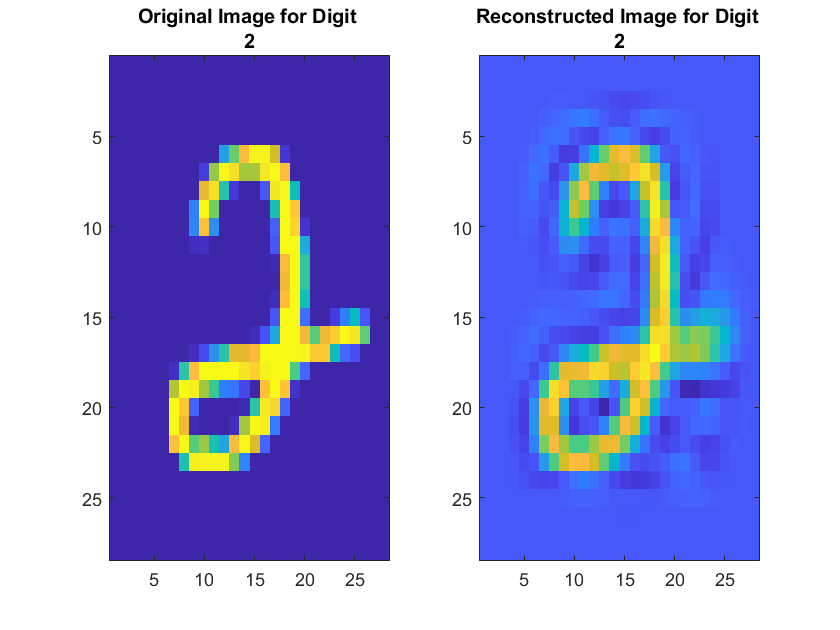

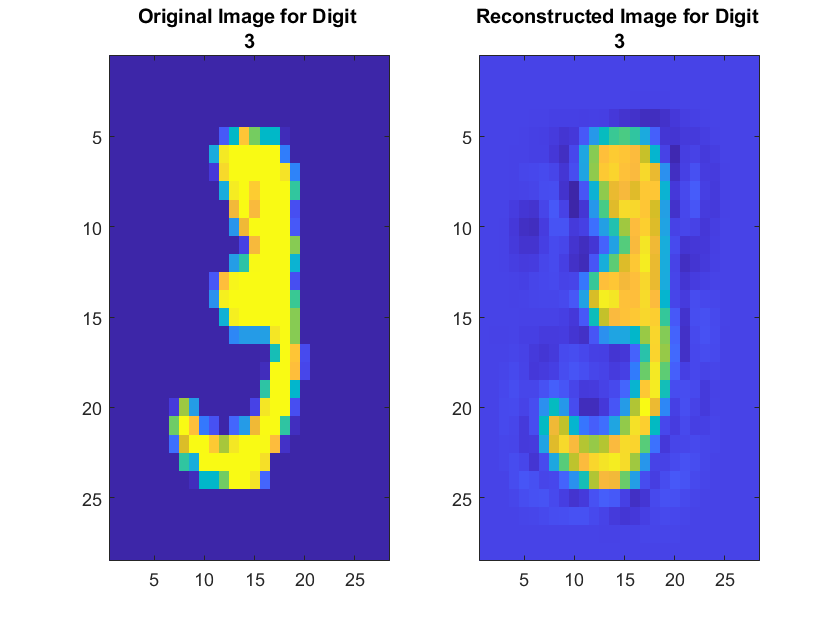

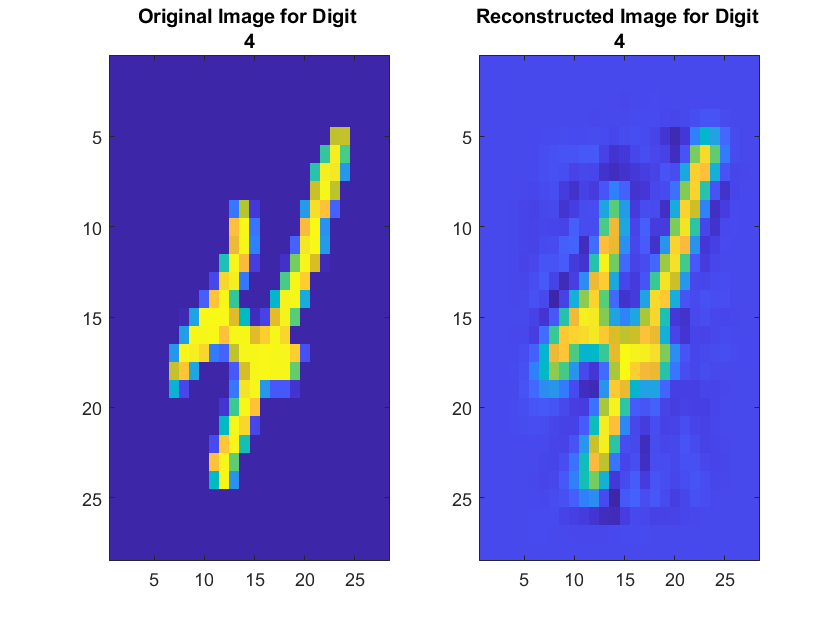

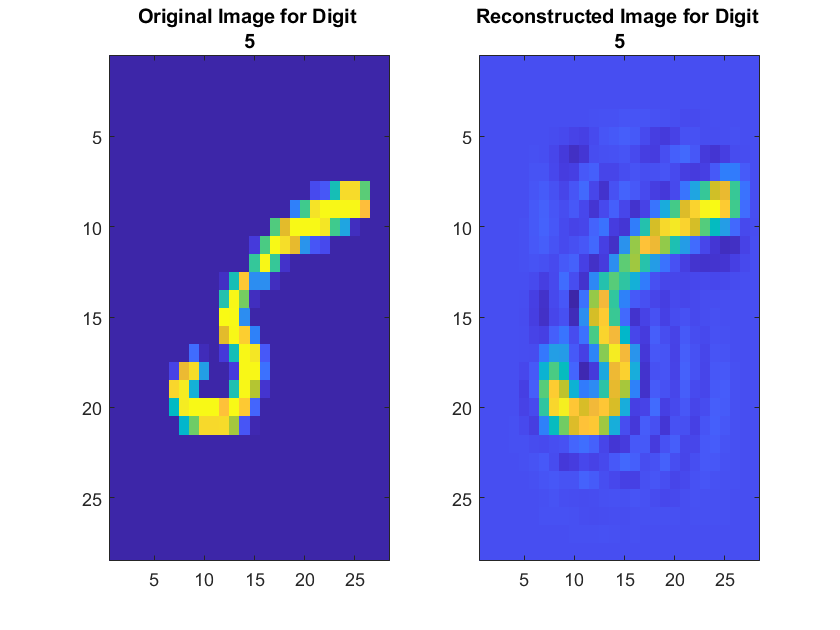

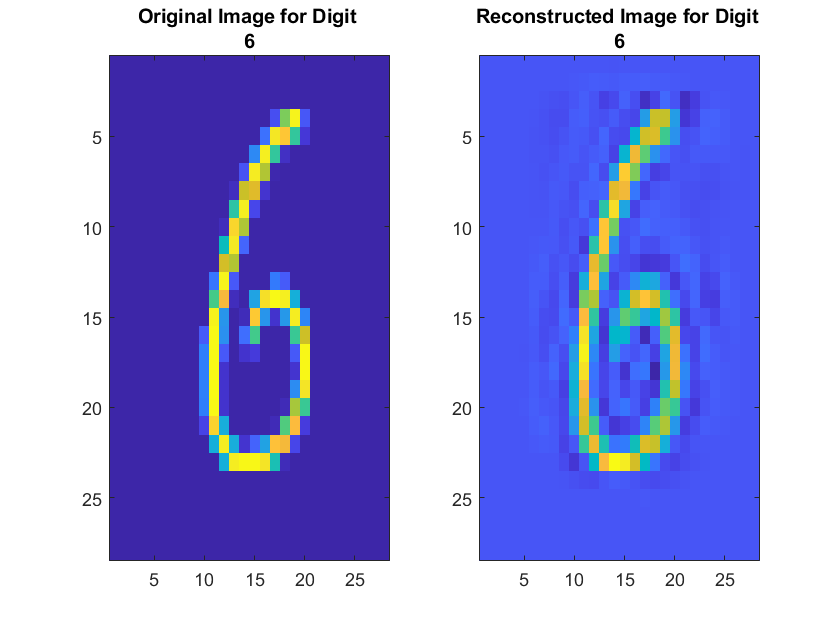

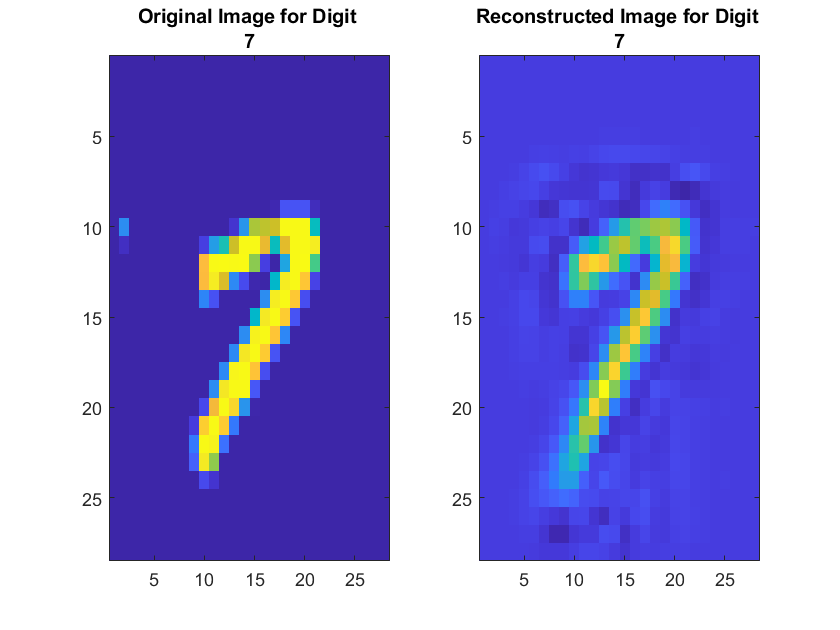

   % Plot below. We reshape the images after adding back the mean vector
   % and then plot
   figure;
   axis equal;
   subplot(1, 2, 1);
   imshow(reshape(mean_vector + digits(:, 2), [28 28]));
   title(["Original Image for Digit " num2str(d)]);
   
   subplot(1, 2, 2);
   imshow(reshape(mean_vector + reconstructed(:, 2), [28 28]));
   title(["Reconstructed Image for Digit " num2str(d)]);
end